## Asse y - Live script di prova 

Dati

clc
close all
clear

Jm=0.074*10^(-3);   % [kg*m^2]
Jp1=1.2135*10^(-4); % [kg*m^2]
Jp2=6.5420*10^(-4); % [kg*m^2]
Jp3=0.5990*10^(-4); % [kg*m^2]

Mx=12; %[kg]

kcs1=1.900*10^7; % [N/m] rig. cinghia tratto 1 specifica ( da moltiplicare per spessore e dividere per lunghezza)
w1=25*10^(-3); % [m] spessore cinghia 1 tratto
kcs2=2.340*10^7; % [N/m] 
w2=15*10^(-3); % [m] spessore cinghia 2 tratto

d1=23.87*10^(-3); % [m] diametro puleggia 1
d2=76.39*10^(-3); % [m] diametro puleggia 2
d3=31.83*10^(-3); % [m] diametro puleggia 3
r1=d1/2 ; r2=d2/2; r3=d3/2;
a1=119*10^(-3); % [m] ; %interasse primo tratto
a2=1036*10^(-3); % [m]; %interasse secondo tratto

Cm=0.45;

Calcolo lunghezze tratti di cinghia

%l1_tot=pi*(r1+r1)+2*sqrt(a1^2+(r1-r2)^2); %lunghessa dell'anello di cinghia
%theta=(r2-r1)/a1;
%l1=(r2-r1)/tan(theta); %tratto chiuso del motore

l1_tot=(2*a1)+(pi/2)*(d1+d2)+((d1-d2)^2)/(4*a1);
l1_intermedio=l1_tot-pi*(r1+r2);
l1=l1_intermedio/2

l1 = 0.1219


%l2_tot=2*pi*r3+2*a2;
%l2=(l2_tot-2*pi*r3)/2; %tratto in zona carrello

l2_tot=(2*a2)+(pi/2)*(d3+d3)+((d3-d3)^2)/(4*a2);
l2_intermedio=l2_tot-pi*(r3+r3);
l2=l2_intermedio/2

l2 = 1.0360


k1=kcs1*w1/l1; k2=kcs2*2*w2/(l2); k3=k2; k4=kcs2*w2/l2;

Calcolo matrici M, D, K

disp('matrice delle masse')

matrice delle masse



M = [Jm+Jp1, 0     , 0  , 0  ;
        0, 2*(Jp3)+Jp2, 0  , 0  ;
        0,    0  , 2*Jp3, 0  ;
        0,    0  ,   0, Mx;]

M =     0.0002         0         0         0
         0    0.0008         0         0
         0         0    0.0001         0
         0         0         0   12.0000



disp('matrice delle rigidezze')

matrice delle rigidezze


K = [2*k1*(r1^2) , -2*k1*r2*r1  ,                0,           0;
  -2*k1*r2*r1     , 2*((r3^2)*(k4+k2) + (k1)*(r2^2))   ,    -2*k4*(r3^2)  ,             -2*k2*r3;
   0              ,  -2*k4*(r3^2) ,            (k3+k4)*(r3^2)*2       ,           -2*k3*(r3);
   0 ,                       -2*k2*r3 ,                        -2*k3*(r3) ,                2*(k3+k2)]

K = 	1.0e+06 *

    0.0011   -0.0036         0         0
   -0.0036    0.0119   -0.0002   -0.0216
         0   -0.0002    0.0005   -0.0216
         0   -0.0216   -0.0216    2.7104



% disp('matrice degli smorzamenti')
C=zeros(4,4)% % 

C =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


% % C=[0, 0 , 0, 0 , 0;
% %    0, 0 , 0, 0 , 0;
% %    0, 0 , 0, 0 , 0;
% %    0, 0 , 0, 0 , 0;
% %    0, 0 , 0, 0 , 0]
F = [Cm;0;0;0] %forcing force on the 4rd coordinate

F =     0.4500
         0
         0
         0


**Calcolo autovalori e autovettori**

(Modi di vibrare e pulsazioni caratteristiche)

%disp('V contiene gli autovettori, "D" contiene gli autovalori su diagonale')
%[v,d]=eig(inv(M)*K);
% the eigenvalues are the nat. freq. at the power of 2
%disp('Matrice v, ogni colonna equivale ad un autovettore: ')
%disp(v);
%disp('Matrice d, matrice diagonale contente gli autovalori: ')
%disp(d);
[V, D]=show_mode(M,K)

mode 1 - natural frequency w = 0.000018 [rad/s] - 0.000003 [Hz] 
A1 = 1.000000 
A2 = 0.312475 
A3 = 0.312475 
A4 = 0.004973 
mode 2 - natural frequency w = 555.292247 [rad/s] - 88.377506 [Hz] 
A1 = 1.000000 
A2 = 0.295520 
A3 = -0.093016 
A4 = -0.004413 
mode 3 - natural frequency w = 2093.109529 [rad/s] - 333.128728 [Hz] 
A1 = 0.055127 
A2 = 0.003946 
A3 = -1.000000 
A4 = 0.000431 
mode 4 - natural frequency w = 4568.545161 [rad/s] - 727.106545 [Hz] 
A1 = 1.000000 
A2 = -0.835179 
A3 = 0.071471 
A4 = 0.000066 


V =     0.9147    0.9552    0.0550    0.7664
    0.2858    0.2823    0.0039   -0.6401
    0.2858   -0.0888   -0.9985    0.0548
    0.0045   -0.0042    0.0004    0.0001


D = 	1.0e+07 *

    0.0000         0         0         0
         0    0.0308         0         0
         0         0    0.4381         0
         0         0         0    2.0872


## Metodo di normalizzazione rispetto alla matrice delle masse M

%pii=zeros(5,1);
%pii_quadro=zeros(5,1);
%W_i= zeros(5,1);
%for ti=1:5
%    
%    pii_quadro(ti,1)=(v(:,ti)'*M*v(:,ti))\1;
%    pii(ti,1)=sqrt(pii_quadro(ti,1));
 %   W_i(ti,1)=sqrt(d(ti,ti));
%end %adesso ho lo scalare pi che rende unitaria la rispettiva massa modale
%K_norm=zeros(5,5);
%M_norm=zeros(5,5);
%mi interessano solo gli ele
%for ti=1:5
%    M_norm(ti,ti)=pii(ti)*v(:,ti)'*M*pii(ti)*v(:,ti);       %rigidezza_modale(ti,ti)=v(:,ti)'*K*v(:,ti);  %M_norm(ti,ti)= massa_modale(ti,ti)/pii(ti)^2; %K_norm(ti,ti)=rigidezza_modale(ti,ti)/M_norm(ti,ti);
%    K_norm(ti,ti)= d(ti,ti);
%end

## ipotesi di smorzamento proporzionale, quindi vale la relazione:

fi'*C*fi= a*(massa_modale)+b(rigidezza_modale)= smorzamento_modale

dove      per i=j  ---> ci= 2*smorzamento*pulsazione_i

              per i!=j ---> ci=0

definizione coeffieciente di smorzamento

z=0.7

z = 0.7000

%C_mx=zeros(5,5);

%for ti=1:5    %C_mx(ti,ti)= 2*massa_modale(ti,ti)*z_smorzamento*W_i(ti,1);
%    C_mx(ti,ti)= 2*z*W_i(ti,1);
%end

%M_norm,K_norm,C_mx
%C_0=v*C_mx*v'
%F_modale = v'*F;

## medoto di normalizzazione della componente unitaria 

%V_n= zeros(5,5);
%for ti=1:5
%    fscala = max(abs(v(:,ti)));
%    for jj=1:5
%       V_n(jj,ti)=v(jj,ti)/fscala;  
%    end
%end
%V_n

massa_modale=zeros(4,4);
rigidezza_modale=zeros(4,4);
C_mx1=zeros(4,4);

W_i= zeros(4,1);
for ti=1:4
    massa_modale(ti,ti) = V(:,ti)'*M*V(:,ti);
    rigidezza_modale(ti,ti) = V(:,ti)'*K*V(:,ti);
    W_i(ti,1)=sqrt(D(ti,ti));
    C_mx1(ti,ti)=2*z*massa_modale(ti,ti)*W_i(ti,1);
end

rigidezza_modale,massa_modale

rigidezza_modale = 	1.0e+03 *

    0.0000         0         0         0
         0    0.1400         0         0
         0         0    0.5356         0
         0         0         0    9.0210


massa_modale = 	1.0e+-3 *

    0.4847         0         0         0
         0    0.4541         0         0
         0         0    0.1223         0
         0         0         0    0.4322



for ti=1:4
    C_mx1(ti,ti)=2*z*sqrt(massa_modale(ti,ti)*rigidezza_modale(ti,ti));
end
C_mx1

C_mx1 =     0.0000         0         0         0
         0    0.3530         0         0
         0         0    0.3583         0
         0         0         0    2.7644



C_1=((V')^-1)*C_mx1*((V)^-1);
F_modale1 = V'*F;


## Confronto della matrici C ricavate dai due metodi:

%disp('C dalla normalizzazione della massa:')
%C_0
disp('C dalla normalizzazione degli autovettori:')

C dalla normalizzazione degli autovettori:


C_1

C_1 = 	1.0e+03 *

    0.0004   -0.0010   -0.0000   -0.0135
   -0.0010    0.0037   -0.0001   -0.0230
   -0.0000   -0.0001    0.0003   -0.0138
   -0.0135   -0.0230   -0.0138    5.0247


## Tracciamento dei grafici:


$$\left(
-\Omega^2M + 1j\Omega C +K
\right)
X = F$$



%thehta1,theta2,theta3,theta4,x,
x0=[0; 0;0 ; l2/2] %inital condition on position

x0 =          0
         0
         0
    0.5180


dotx0=[0; 0; 0 ;0]; %initial condition con speed
%evaluation of the coeffcient of the linear comb. of modes
coeff=coeff_free_vib(V,D,x0,dotx0);
disp('coefficients of the linear combination')

coefficients of the linear combination


disp(coeff)

         0
   58.3308
         0
  -57.7036
         0
   21.8718
         0
    0.7328



disp('time response of the two coordinates')

time response of the two coordinates



%vector with the frequencies at wich evaluete the solutions (200 solutions)
wmax= 8000;
Om=-0:(2*wmax)/200:2*wmax;

%solves and plots the amplitude of vibrations of the coordinates
disp('C nulla   ')

C nulla   


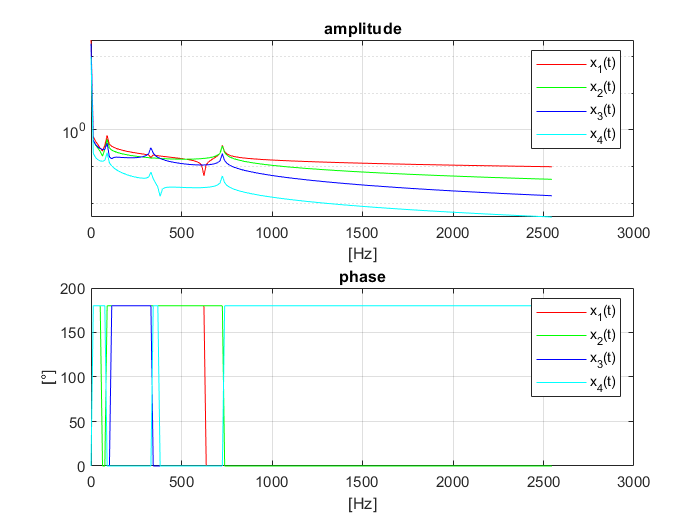

plotForcedDumped(M,C,K,F,Om)

%disp('Grafici con C ricavata dalla normalizzazione della masse:')
%plotForcedDumped(M,C_0,K,F,Om)
disp('Grafici con C ricavata dalla normalizzazione degli autovettori:')

Grafici con C ricavata dalla normalizzazione degli autovettori:


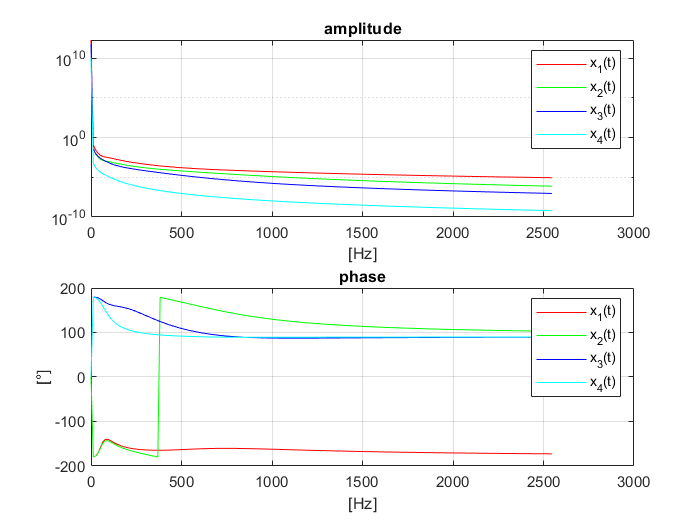

plotForcedDumped(M,C_1,K,F,Om)

## return 

## Vibrazioni libere


return
%column vectors
x0=[0; 0; 0; 0 ; l2/4] %inital condition on position
dotx0=[0; 0; 0; 0; 0]; %initial condition con speed
%evaluation of the coeffcient of the linear comb. of modes
coeff=coeff_free_vib(v,d,x0,dotx0);
disp('coefficients of the linear combination')
disp(coeff)

disp('time response of the two coordinates')
plot_free_vib(v,d,coeff);


sistema Forzato


$$\left(
-\Omega^2M + 1j\Omega C +K
\right)
X = F$$


  F = [1; 0;0;0;0] ;%forcing force 

Mnorm = inv(V).*M.*V;
Knorm = inv(V).*K.*V;

xi=0.1;
Cnorm=2*xi.*Mnorm.*sqrt(D)
C=V.*Cnorm.*inv(V)

%vector with the frequencies at wich evaluete the solutions (200 solutions)
Om=1*2*pi:(2*w_max)/200:2*w_max;

%solves and plots the amplitude of vibrations of the coordinates

plotForcedDumped(M,C,K,F,Om)
plotForcedDumped(Mnorm,Cnorm,Knorm,F,Om)